# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 신동민**

**학번**** : 201716219**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 


x = [1, 2, 2, 1]; N =4; X = dft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


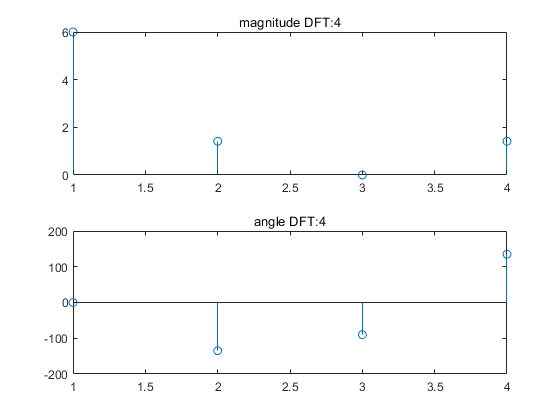

subplot(2,1,1);
stem(magX);title('magnitude DFT:4');
subplot(2,1,2);
stem(phaX);title('angle DFT:4');


x = [1, 2, 2, 1]; N =4;
Xi = idft(x,N);
magXi = abs(Xi), phaXi = angle(Xi)*180/pi

magXi =     1.5000    0.3536    0.0000    0.3536


phaXi =          0  135.0000   90.0000 -135.0000


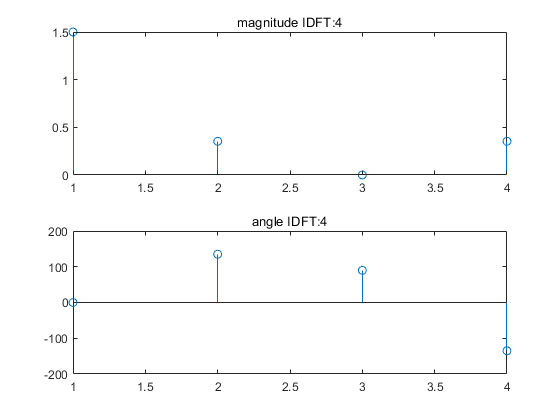

subplot(2,1,1);
stem(magXi);title('magnitude IDFT:4');
subplot(2,1,2);
stem(phaXi);title('angle IDFT:4');

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.


x = [1, 2, 2, 1, zeros(1,12)]; N =16; X = dft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


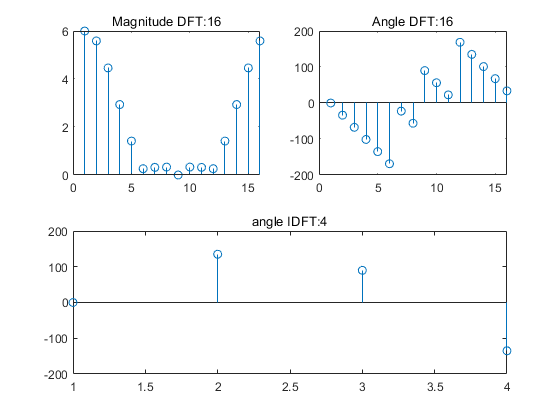

subplot(2,2,1);
stem(magX);title('Magnitude DFT:16');
subplot(2,2,2);
stem(phaX);title('Angle DFT:16');


Xi = idft(x,N);
magXi = abs(Xi), phaXi = angle(Xi)*180/pi

magXi =     0.3750    0.3491    0.2788    0.1835    0.0884    0.0163    0.0198    0.0207    0.0000    0.0207    0.0198    0.0163    0.0884    0.1835    0.2788    0.3491


phaXi =          0   33.7500   67.5000  101.2500  135.0000  168.7500   22.5000   56.2500  -90.0000  -56.2500  -22.5000 -168.7500 -135.0000 -101.2500  -67.5000  -33.7500


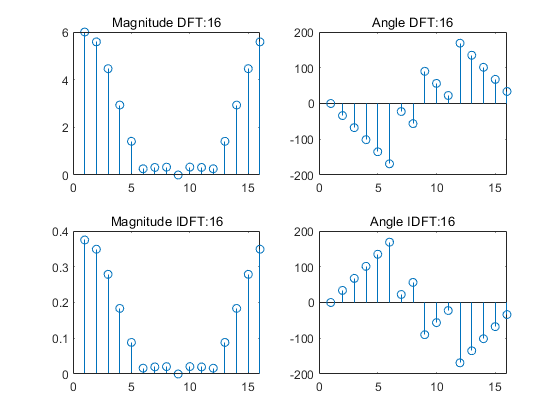

subplot(2,2,3);
stem(magXi);title('Magnitude IDFT:16');
subplot(2,2,4);
stem(phaXi);title('Angle IDFT:16');

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

$\overset{~}{X} \left(k\right)$=$\sum_{n=0}^N \overset{~}{x} \left(n\right)W_N^{\mathrm{nk}} \;=\sum_{n=0}^N \overset{~}{x} \left(n\right)W_4^{\mathrm{nk}} =\sum_{n=0}^N \overset{~}{x} \left(n\right)\left(-j\right)^n$


$$\overset{~}{X} \left(0\right)=4+1+\left(-1\right)+1=5$$


$\overset{~}{X} \left(1\right)$=$\sum_{n=0}^N \overset{~}{x} \left(n\right)\left(-j\right)^n =4-j+1+j=5$

$\overset{~}{X} \left(2\right)$=$\sum_{n=0}^N \overset{~}{x} \left(n\right)\left(-j\right)^{2n} =4-1-1-1=1$


$$\begin{array}{l}
\overset{~}{X} \left(3\right)=\sum_{n=0}^N \overset{~}{x} \left(n\right)\left(-j\right)^{3n} =4+j+1-j=5\\

\end{array}$$



xn= [4,1,-1,1]; N=4;
Xk = dfs(xn,N);
Xk

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

$\overset{~}{X} \left(k\right)$=$\sum_{n=0}^N \overset{~}{x} \left(n\right)W_N^{\mathrm{nk}} \;=\sum_{n=0}^N \overset{~}{x} \left(n\right)W_5^{\mathrm{nk}}$        , $W_5 =e^{-\mathrm{j2}\frac{\pi }{5}} \;$


$$\overset{~}{X} \left(0\right)=1+0-1-1+0=-1$$


$\overset{~}{X} \left(1\right)$=$\sum_{n=0}^N \overset{~}{x} \left(n\right)W_5^n$

$\overset{~}{X} \left(2\right)$=$\sum_{n=0}^N \overset{~}{x} \left(n\right)W_5^{2n}$


$$\overset{~}{X} \left(3\right)=\sum_{n=0}^N \overset{~}{x} \left(n\right)W_5^{3n}$$


xn= [1,0,-1,-1,0]; N=5;
Xk = dfs(xn,N);
Xk

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

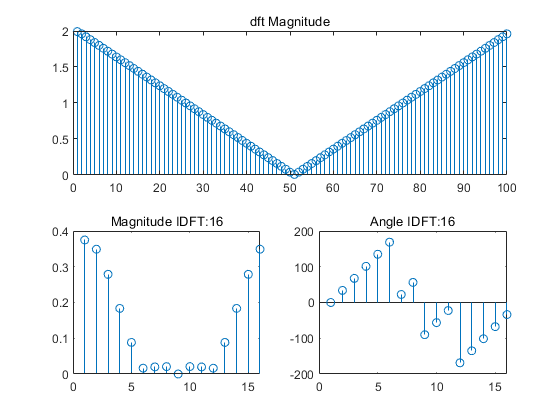

n = [0:1:99];
x = (sinc((n-50)/2)).^2;
X = dft(x,100); 
% magX = abs(X(1:1:51));
% k = 0:1:50; w = 2*pi/100*k;

magX = abs(X);
phaX = angle(X)*180/pi;
subplot(2,1,1); stem(magX); title('dft Magnitude');

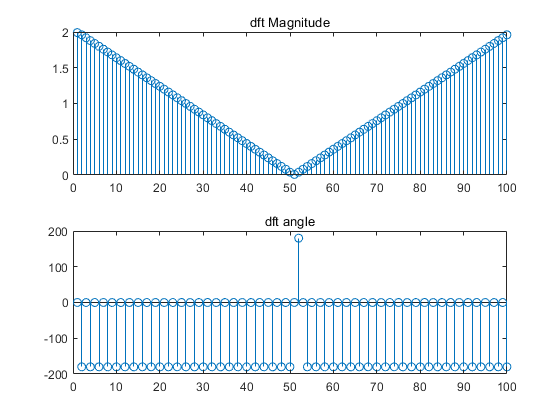

subplot(2,1,2); stem(phaX); title('dft angle')

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

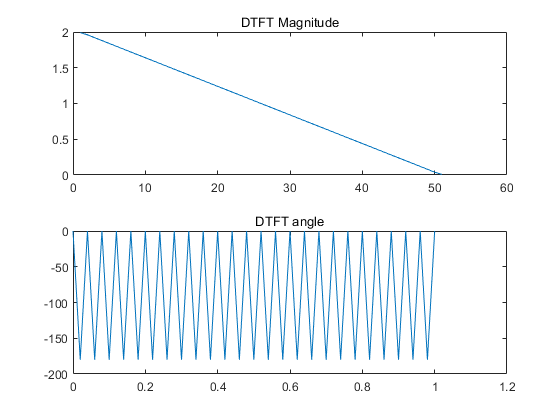

n = [0:1:99];
x = (sinc((n-50)/2)).^2;
X = dft(x,100); 
magX = abs(X(1:1:51));
phaX = angle(X(1:1:51))*180/pi;
k = 0:1:50; w = 2*pi/100*k;
subplot(2,1,1); plot(magX);title('DTFT Magnitude')
subplot(2,1,2); plot(w/pi,phaX); title('DTFT angle')

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

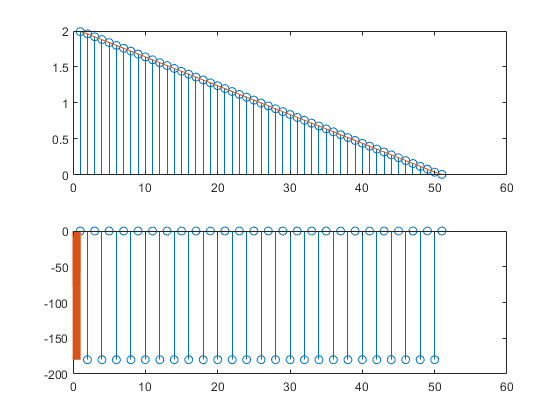

subplot(2,1,1); 
stem(magX)
hold on
plot(magX)
hold off

subplot(2,1,2); 
stem(phaX)
hold on
plot(w/pi,phaX)
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

function [Xk] = dft(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end
function [Xk] = idft(Xk,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
Xk = (Xk * WNnk)/N;
end

function [Xk] = dfs(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [Xk] = idfs(Xk,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
Xk = (Xk * WNnk)/N;
end
